# HW3 Team Homework SI - Modeling

## AMSC420 - Jiatong Liang and Adam Levav

## Question 1 Preprocessing Data

% Reading in the Excel file as a table then converting it into a matrix
mytable = readtable('project8_data.xlsx');
x = mytable{2:3,13:end};
x = transpose(x)

x =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0



% 1st column: cumulative number of detected infections
% 2nd column: Covid-19 related deaths reported in that specific county/city

## Setting up the data

Tmax = 119;

for i = 1:size(x, 1)
    if x(i,1) >= 5
        break
    end
end
t0 = i

t0 = 52

I = zeros(120,1);

% Here we are copying over 119 ADDITIONAL days so there's 120 days in total
for j = 0:119
    I(j+1, 1) = x(t0 + j, 1);
end
I 

I =      5
     7
     7
     9
    13
    14
    17
    17
    22
    26


% Max population is pulled from Population column
Nmax = 236842

Nmax = 236842


% Nmin is maximum infected population based on our data of 120 entries
Nmin = 1 + I(120, 1)

Nmin = 2583

## Problem 1 part a)

N = Nmin;
coeff = 6/(Tmax*(Tmax+1)*(2*Tmax + 1));
summation = 0;

% Because of MATLAB indexing, we want to start with I(2) and end with
% I(120) for the summation since the lecture has indexing with I(0) but in
% MATLAB that's equivalent to I(1)
for t = 1:Tmax
    summation = summation + t*log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1))));
end
% This calculates betahat
betahat = coeff * summation

betahat = 0.0972

J = 0;

% This will calculate J(beta, N)
for t = 1:(Tmax+1)
    J = J + abs(betahat*t - log(I(t)/(N-I(t))) + log(I(1)/(N-I(1))))^2;
end

J

J = 102.0515

I_fctn = @(x) (N*I(1)) / (I(1) + (N-I(1))*exp(-1*betahat*x));
fplot(I_fctn,[0 120]);

## Problem 1 part a)

N = Nmax;
coeff = 6/(Tmax*(Tmax+1)*(2*Tmax + 1));
summation = 0;

% Because of MATLAB indexing, we want to start with I(2) and end with
% I(120) for the summation since the lecture has indexing with I(0) but in
% MATLAB that's equivalent to I(1)
for t = 1:Tmax
    summation = summation + t*log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1))));
end
% This calculates betahat
betahat = coeff * summation

betahat = 0.0721

J = 0;

% This will calculate J(beta, N)
for t = 1:(Tmax+1)
    J = J + abs(betahat*t - log(I(t)/(N-I(t))) + log(I(1)/(N-I(1))))^2;
end

J

J = 240.8491

I_fctn = @(x) (N*I(1)) / (I(1) + (N-I(1))*exp(-1*betahat*x));
fplot(I_fctn,[0 120]);

## Problem 1 part b)

J = zeros(1,1);
Jold = inf;
N = 1 + I(120);
a = 6/(Tmax*(Tmax+1)*(2*Tmax + 1));
summation1 = 0;
summation2 = 0;

for t = 1:Tmax
    summation2 = summation2 + t*log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1))));
end

for t = 1:Tmax
    summation1 = summation1 + abs(log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1)))))^2;
end

JN = summation1 - a*(summation2^2);
J(1,1) = JN;
i = 2;

while JN < Jold
    Jold = JN;
    N = N+1
    summation1 = 0;
    summation2 = 0;

    for t = 1:Tmax
        summation2 = summation2 + t*log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1))));
    end

    for t = 1:Tmax
        summation1 = summation1 + abs(log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1)))))^2;
    end

    JN = summation1 - a*(summation2^2);
    J(i,1) = JN;
    i = i + 1;
end

N = 2584

N = 2585

N = 2586

N = 2587

N = 2588

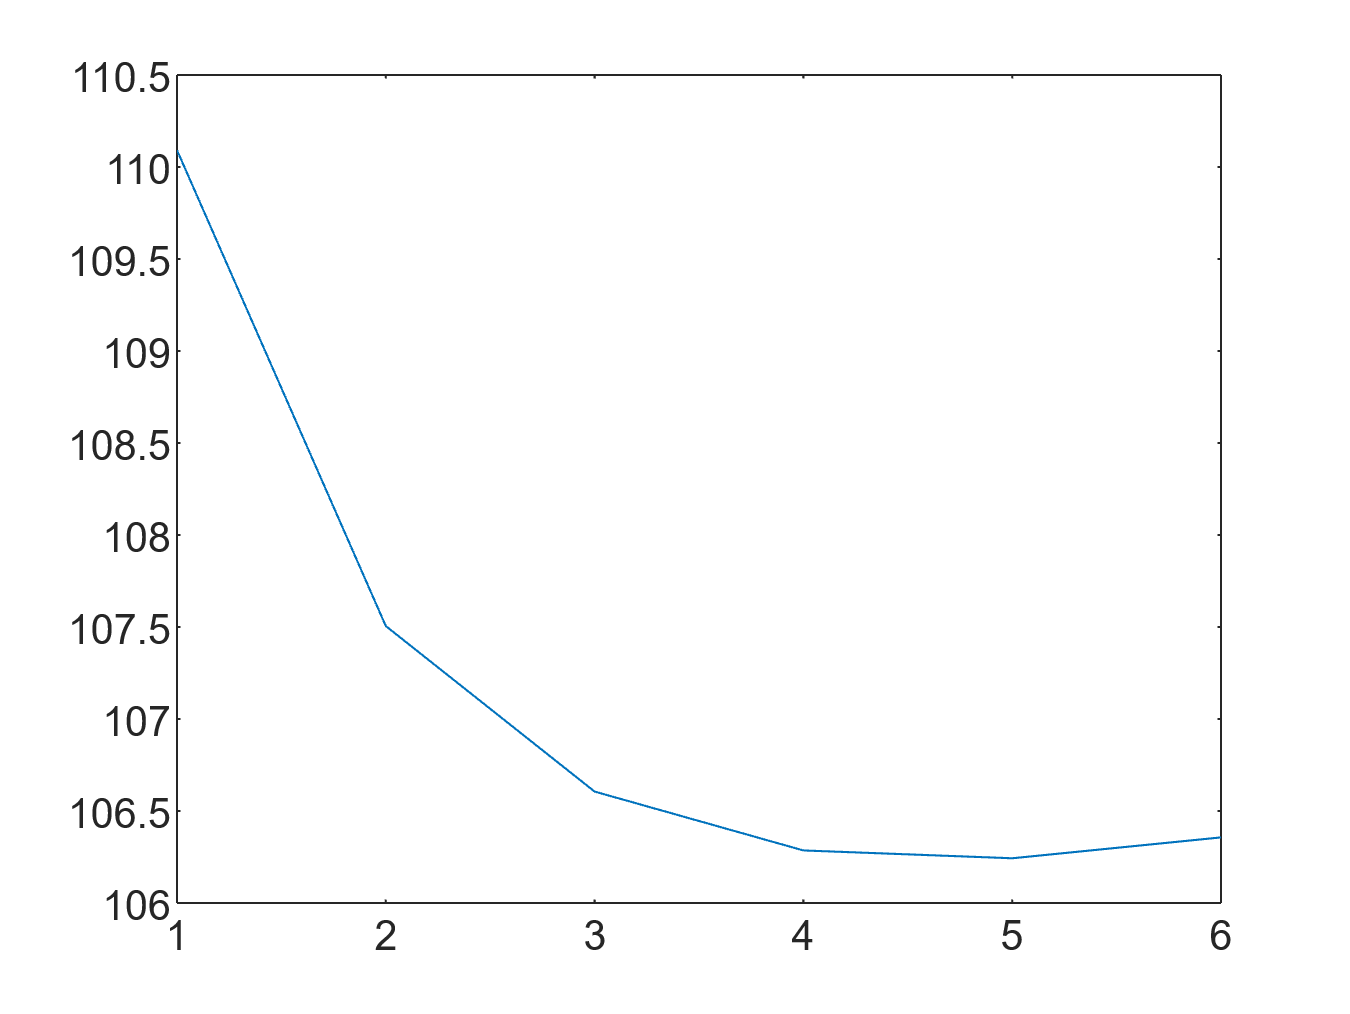


summation = 0;
for t = 1:Tmax
    summation = summation + t*log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1))));
end

plot(J);

N

N = 2588

betahat = a*summation

betahat = 0.0965


JBN = 0;

% This will calculate J(beta, N)
for t = 1:(Tmax+1)
    JBN = JBN + abs(betahat*t - log(I(t)/(N-I(t))) + log(I(1)/(N-I(1))))^2;
end

JBN

JBN = 98.0832


I_fctn = @(x) (N*I(1)) / (I(1) + (N-I(1))*exp(-1*betahat*x));
fplot(I_fctn,[0, 120]);

## Problem 1 part b) part iv

J = zeros(1,1);
i = 1;
N = Nmin;
JN = 0;

while N < Nmax
    summation1 = 0;
    summation2 = 0;

    for t = 1:Tmax
        summation2 = summation2 + t*log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1))));
    end

    for t = 1:Tmax
        summation1 = summation1 + abs(log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1)))))^2;
    end

    JN = summation1 - a*(summation2^2);
    J(i,1) = JN;
    i = i + 1;
    N = N + 1;
end

plot(J)

min(J)

ans = 106.2431

## Problem 1 part c

new_I = zeros(1,1);
i = 1;
N = Nmin;
coeff = 6/(Tmax*(Tmax+1)*(2*Tmax + 1));

while N < Nmax
    summation = 0;
    X(i) = N;
    % Because of MATLAB indexing, we want to start with I(2) and end with
    % I(120) for the summation since the lecture has indexing with I(0) but in
    % MATLAB that's equivalent to I(1)
    for t = 1:Tmax
        summation = summation + t*log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1))));
    end
    % This calculates betahat
    betahat = coeff * summation;

    summation = 0;
    for t = 0:Tmax
        summation = summation + abs(I(t+1) - (N*I(1))/(I(1) + (N-I(1))*exp(-1*betahat*t)))^2;
    end

    new_I(i,1) = summation;
    i = i + 1;
    N = N + 1;
end

plot(X, new_I)
min(new_I)

ans = 1.3327e+07


disp(2)

     2



## Problem 2 Part 1

Create the rates of active infection I(t) using a difference formula: I(t) = v(t + t0 + τ ) − v(t + t0 − τ ), for 0 ≤ t ≤ Tmax. The parameter τ is related to incubation and infection period. Set τ = 7 days for now (the assumption is that the infection lasts up to 14 days). Plot I = I(t), the rates of active infection.

v = x(:,1); % cumulative number of infections
tau = 7;    % parameter related to incubation and infection period
% t0 calculated above: t0 = 52
% Tmax defined above: Tmax = 119

I = zeros(Tmax+1,1); % note that I(t) represent the value of I at t+1
for t=0:Tmax
    I(t+1) = v(t+t0+tau) - v(t+t0-tau);
end
I

I =     17
    22
    26
    34
    35
    45
    52
    58
    68
    77


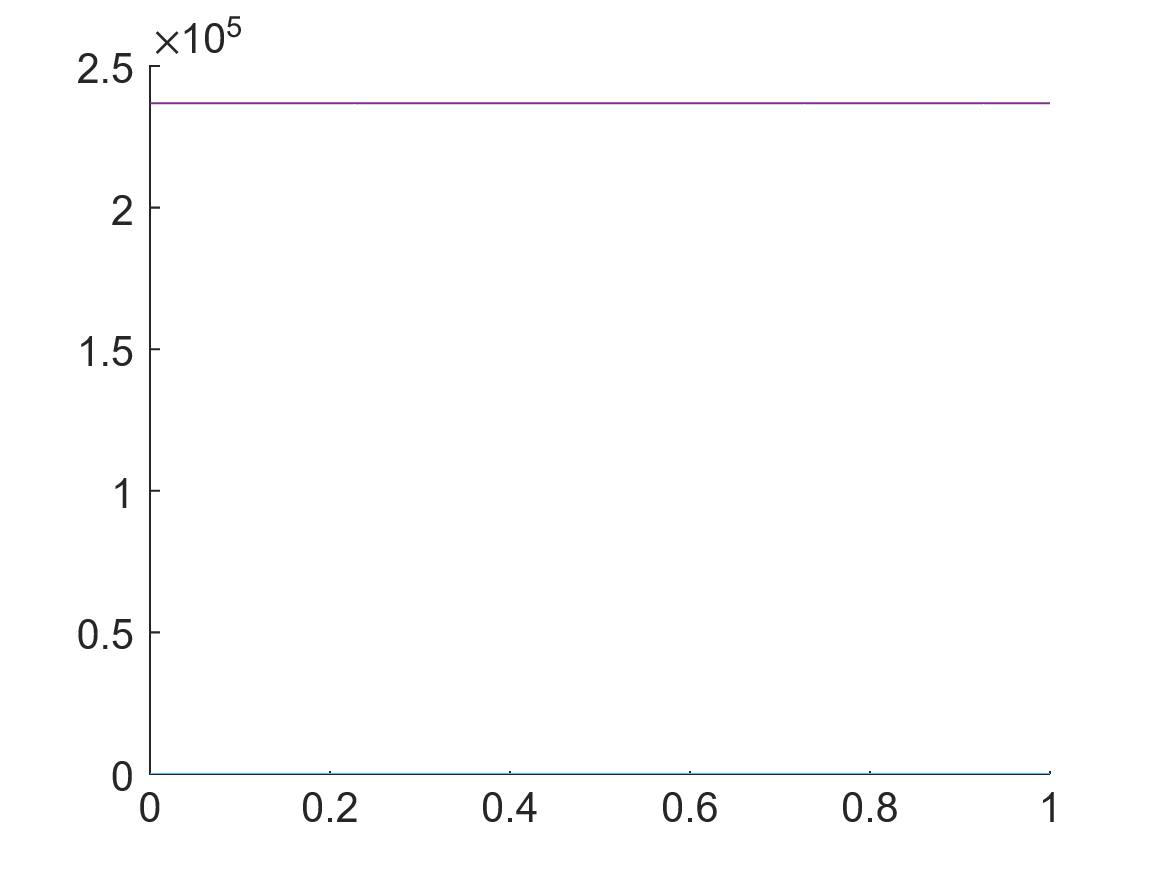

plot(0:Tmax, I)

## Problem 2 Part 2

Implement an Euler scheme for solving the SIR Model with step size h = 0.01. Denote by (Ssim(t), Isim(t), Rsim(t)) the numerical solution. Use initialization S(0) = N , I(0) from the data set, R(0) = 0. For this problem, the unknown parameters are α, β, N .

% See appendix for euler_scheme function

% Test the euler scheme
[Stest, Itest, Rtest] = euler_scheme(I(1), Tmax, 0.2, 0.4, Nmax)

Stest = 1.0e+05 *

    2.3684
    2.3683
    2.3683
    2.3681
    2.3680
    2.3678
    2.3676
    2.3674
    2.3671
    2.3667


Itest = 1.0e+04 *

    0.0017
    0.0021
    0.0025
    0.0031
    0.0038
    0.0046
    0.0056
    0.0069
    0.0084
    0.0103


Rtest = 1.0e+05 *

         0
    0.0000
    0.0001
    0.0001
    0.0002
    0.0003
    0.0004
    0.0005
    0.0007
    0.0009


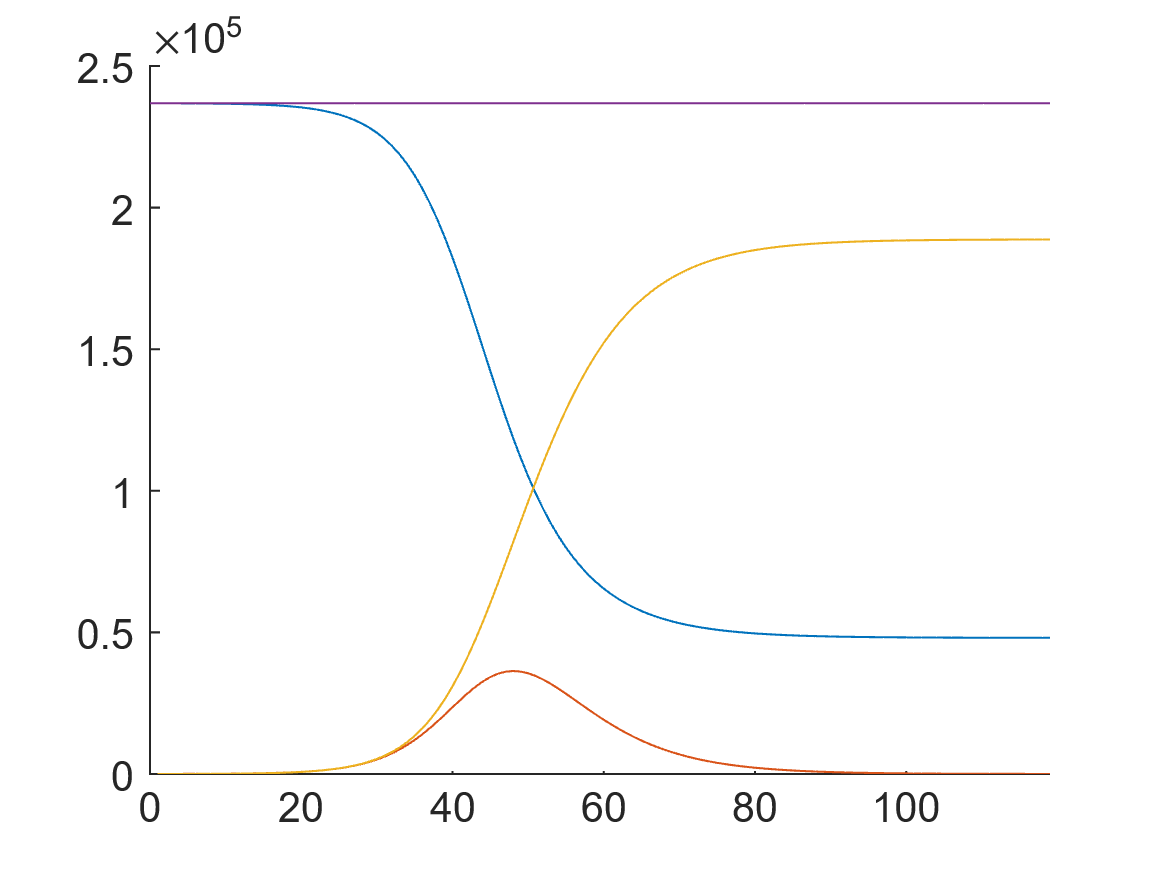

figure
hold on
plot(Stest)
plot(Itest)
plot(Rtest)
fplot(Nmax)
xlim([0, Tmax])
hold off

% Compute set omega of possible values for (alpha, beta, N):
alphaSet = [1/10, 1/9, 1/8, 1/7, 1/6, 1/5];
R0Set = [0.8, 0.9, 0.95, 1, 1.05, 1.1, 1.15, 1.2, 1.3, 1.4, 1.5, 1.6]
% The final value is cut off in the PDF; I assume it's 1.6
NfracSet = 0.1:0.1:1;
Nmax = 236842; % County population; copied from data set

alphaLen = length(alphaSet);
betaLen = length(R0Set);
NLen = length(NfracSet);
[alphaLen, betaLen, NLen]
NfracSet

%omega = zeros(alphaLen*betaLen*NLen,3)
omega = zeros(alphaLen, betaLen, NLen, 3);
for alphaInd = 1:alphaLen
    for R0Ind = 1:betaLen
        for NfracInd = 1:NLen
            alpha = alphaSet(alphaInd);
            beta = alpha * R0Set(R0Ind);
            N = Nmax * NfracSet(NfracInd);
            
            %omegaInd = sub2ind(length(omega), alphaInd, R0Ind, NfracInd);
            %omega(omegaInd) = [alpha, beta, N];
            omega(alphaInd, R0Ind, NfracInd, :) = [alpha, beta, N];
        end
    end
end
omega

## Problem 2 Part 3

% J(alphaInd, betaInd, NInd) contains the L2 norm for 
% the Euler scheme with the associated params
J = zeros(alphaLen, betaLen, NLen); 
%Isims = zeros(alphaLen, betaLen, NLen, Tmax+1);

for alphaInd = 1:alphaLen
    for betaInd = 1:betaLen
        for NInd = 1:NLen
            params = num2cell(reshape(omega(alphaInd, betaInd, NInd, :), 1, []));
            [alpha, beta, N] = params{:};
            [Ssim, Isim, Rsim] = euler_scheme(I(1), Tmax, alpha, beta, N);
            l2error = norm(Isim - I, 2)^2;

            %[alpha, beta, N, l2error]
            %Isims(alphaInd, betaInd, NInd, :) = Isim;
            J(alphaInd, betaInd, NInd) = l2error;
        end
    end
end     
J

J = J(:,:,1) =

   1.0e+08 *

    0.1428    0.1401    0.1380    0.1352    0.1313    0.1261    0.1192    0.1110    0.1008    0.1683    0.4816    1.0787
    0.1432    0.1405    0.1383    0.1352    0.1309    0.1248    0.1168    0.1075    0.1045    0.2278    0.6085    1.1198
    0.1436    0.1409    0.1386    0.1353    0.1303    0.1232    0.1136    0.1033    0.1158    0.2961    0.6455    0.9958
    0.1441    0.1415    0.1391    0.1353    0.1296    0.1210    0.1095    0.0987    0.1348    0.3215    0.5522    0.7760
    0.1446    0.1421    0.1396    0.1355    0.1286    0.1180    0.1040    0.0940    0.1420    0.2576    0.3853    0.5615
    0.1452    0.1428    0.1403    0.1356    0.1273    0.1136    0.0965    0.0862    0.1024    0.1423    0.2419    0.4203


J(:,:,2) =

   1.0e+08 *

    0.1428    0.1401    0.1380    0.1351    0.1312    0.1258    0.1188    0.1105    0.1051    0.2497    1.1128    3.5046
    0.1432    0.1405    0.1382    0.1351    0.1307    0.1245    0.1162    0.1070    0.1182    0

## Problem 2 Part 4

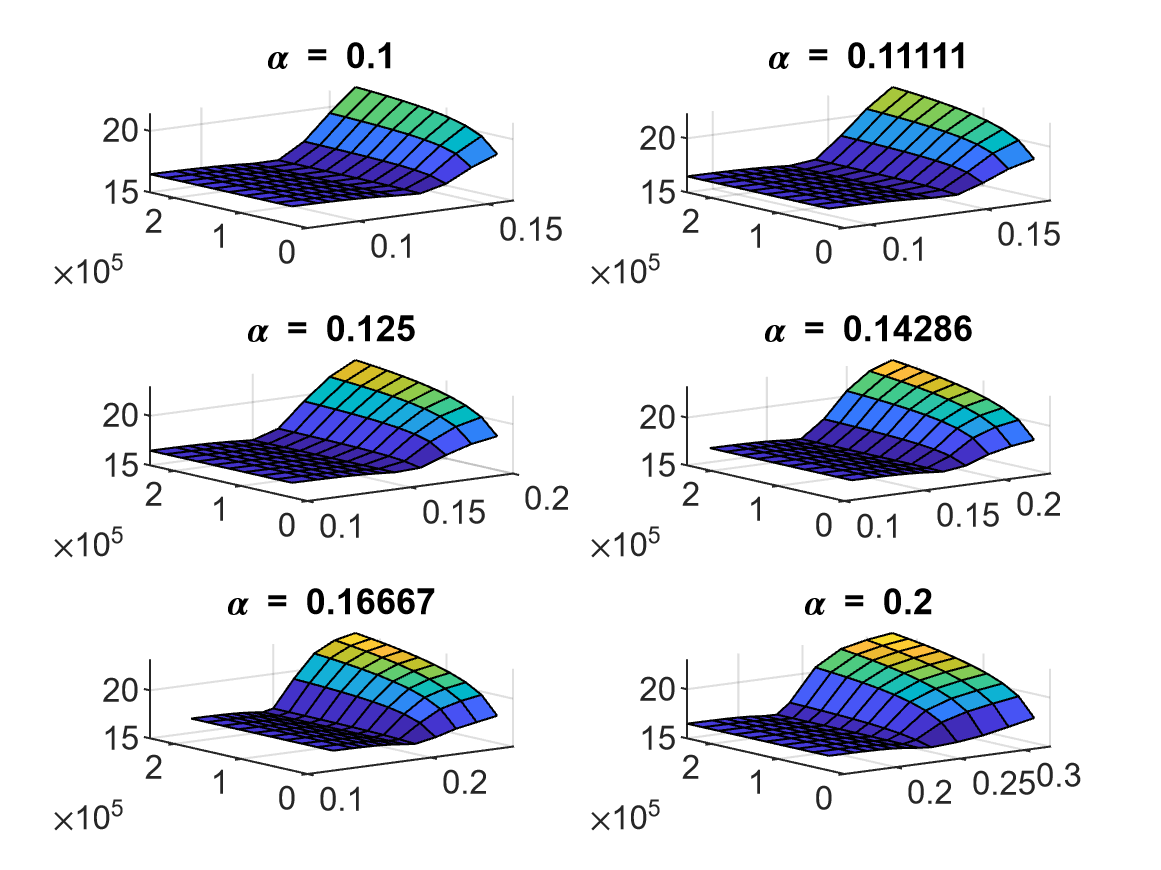

%tiledlayout(alphaLen,1)
figure
tiledlayout('flow')

for alphaInd = 1:alphaLen
    nexttile

    betas = omega(alphaInd, :, :, 2);
    Ns = omega(alphaInd, :, :, 3);
    betas = reshape(betas, betaLen, []);
    Ns = reshape(Ns, [], NLen);

    values = reshape(J(alphaInd, :, :), betaLen, NLen);
    surf(betas, Ns, log(values))
    title(['\alpha = ', num2str(alphaSet(alphaInd))])
end

## Appendix

function [Sout, Iout, Rout] = euler_scheme(I0, Tmax, alpha, beta, N)
    h = 0.01; % step size; I assume it's measured in terms of (fractions of) days
    Nsteps = Tmax/h+1; % number of iterations

    % vectors storing the values at each step
    % the ith entry in each vector is the value at the (i-1)th time step,
    % e.g. Ssim(i) is the approximate value of S at time t = h*(i-1)
    Ssim = zeros(Nsteps,1);
    Isim = zeros(Nsteps,1);
    Rsim = zeros(Nsteps,1);
    
    % Initialization
    Ssim(1) = N;
    Isim(1) = I0;
    Rsim(1) = 0;

    % Steps
    for i = 2:Nsteps
        % t = h*(i-1);
        [Sprev, Iprev, Rprev] = deal(Ssim(i-1), Isim(i-1), Rsim(i-1));
        
        dSdt = -beta * Sprev * Iprev / N;
        dIdt =  beta * Sprev * Iprev / N - alpha * Iprev;
        dRdt = alpha * Iprev;
        %[dSdt, dIdt, dRdt]

        Ssim(i) = Sprev + dSdt * h;
        Isim(i) = Iprev + dIdt * h;
        Rsim(i) = Rprev + dRdt * h;
    end
    % We only care about the values at the day intervals
    Sout = Ssim(1:(1/h):end);
    Iout = Isim(1:(1/h):end);
    Rout = Rsim(1:(1/h):end);

end